%setting basic info
%clear all

global MONKEYDIR
MONKEYDIR = 'C:/Users/Orsborn Lab/OneDrive - UW/projects/Brain EEG/data';
addpath(genpath([MONKEYDIR '/m/']))
drive_base = 'LM1_ECOG';

%trial-alignment parameters
tBefore = -1e2;
tAfter  = 2e2;            
bn = [tBefore tAfter];
trig = 'StartOn';
lfpType = 'lfp';

%%  get metadata to find days/recs w/ same drive, orientation etc.
%get visEP 'sessions'
taskSessions = VisEP_Database;

%get sessions for 'drive' of interest
driveSessions = makeDriveDatabase(drive_base,{'180321','180415'});

%merge to get sessions w/ labview, split by drive
Sessions = mergeTaskDriveSessions(taskSessions, driveSessions);

%convert to a cell (#sessions x N) rather than nested cells b/c easier  to
%work wiith
Sessions = cat(1, Sessions{:});

%get driveName and theta
driveNames = Sessions(:,3);
driveTheta = [Sessions{:,7}];

%find unique driveNames and the theta for each one
[unique_driveNames, inds] = unique(driveNames);
unique_driveTheta = driveTheta(inds);
nDrives = length(unique_driveNames);

%sub-sampling of sessions if desired
%driveNameAnalyze = unique_driveNames; %all data
driveNameAnalyze = {'LM1_ECOG_3'};
useSess          = ismember(driveNames, driveNameAnalyze);

SessAnalyze       = Sessions(useSess,:);
DayAnalyze        = Sessions(useSess,1);
DriveNamesAnalyze = driveNames(useSess);

trialInfo.loweredE_SC32 = 1; 
trialInfo.exampleSC32 = 6;

%load all relevant trials
nSess = size(SessAnalyze,1);
eTrs = [];

for iD=1:nSess
    %we load the regular trials
    trFN = [MONKEYDIR '/' DayAnalyze{iD} '/mat/Trials.mat'];
    load(trFN,'Trials')
    
    %find out the loweredElectrodes
    if trialInfo.loweredE_SC32
        trialInfo.Ndrives = size(Trials(1).Depth,2);
        trialInfo.depthProfile = (Trials(1).Depth{1,2})'; % in micron
        var_temp = 1:length(trialInfo.depthProfile);
        var_temp(trialInfo.depthProfile > 0) = [];
        trialInfo.badSC32 = var_temp;
    else
        trialInfo.badSC32 = [];
    end
    trialInfo.goodSC32 = setdiff(1:32,trialInfo.badSC32);
    
    
    %load error trials
    eTrFN = [MONKEYDIR '/' DayAnalyze{iD} '/mat/ErrorTrials.mat'];
    load(eTrFN, 'ErrorTrials');
    sess_trial_size(nSess) = size(ErrorTrials,2);
    
    %visEPs have taskcode = 1 (touch task used)
    visStimTrials = ErrorTrials( getTaskCode(ErrorTrials)==1 );
    
    %patch work to fix the channel ID problem
    if ~isfield(visStimTrials,'ChannelID')
        for i = 1:length(visStimTrials)
            visStimTrials(i).ChannelID(1) = Trials(1).ChannelID(1);
            visStimTrials(i).ChannelID(2) = Trials(1).ChannelID(2);
        end
        disp('Filled the channelID structure')
    end
   
    dayTrials = visStimTrials;

    
    %load all trial data + position info of electrodes
    [trLfpData_ECOG32, eIDs, t, Pchamber_byDay{iD}] = loadTrLFP_session(dayTrials, SessAnalyze(iD,:), 'LM1_ECOG_3', trig, bn, lfpType);
    %load SC32 trials
    [trLfpData_SC32, eIDs, t, Pchamber_byDay{iD}] = loadTrLFP_session(dayTrials, SessAnalyze(iD,:), 'LM1_SC32_1', trig, bn, lfpType);
    
    trialInfo.N_ECOG = size(trLfpData_ECOG32,2);
    trialInfo.goodE = [1:trialInfo.N_ECOG trialInfo.goodSC32];
    trialInfo_all(iD) = trialInfo;
    
    %stack arrays together
    trLfpData = cat(2,trLfpData_ECOG32,trLfpData_SC32);

    %calculate meanrfp for each channel
    meanLFP(iD,:,:) = squeeze((mean(trLfpData)));%iD = 1 for ECOG
    
%     %calculate correlations across trials
%     visp = squeeze(nanmean(trLfpData));
%     r_visp_e = corrcoef(visp'); % columns are rvs i.e. electrodes, and rows are time points
%     
%     if iD == 1
%         r_visp_e_all(iD,:,:) = r_visp_e;
%     else
%         if size(r_visp_e) < size( r_visp_e_all,[2 3])
%             r_visp_e = padarray(r_visp_e, size( r_visp_e_all,[2 3]) - size(r_visp_e), 'post');
%         elseif size(r_visp_e) > size( r_visp_e_all,[2 3])
%             r_visp_e = padarray(r_visp_e, size(r_visp_e) - size( r_visp_e_all,[2 3]) , 'post');
%         else
%             
%         end
%         r_visp_e_all(iD,:,:) = r_visp_e;
%     end
%     
%     r_ECOG(iD) = mean(mean(r_visp_e(1:trialInfo.N_ECOG,1:trialInfo.N_ECOG)));
%     r_SC32(iD) = mean(mean(r_visp_e(trialInfo.N_ECOG + trialInfo.goodSC32, trialInfo.N_ECOG + trialInfo.goodSC32)));
%     
%     %only look at lowered electrodes
%     r_ECOG_SC32(iD) = mean(mean(r_visp_e(1:trialInfo.N_ECOG,trialInfo.N_ECOG + trialInfo.goodSC32)));
    
    %wrap up and clean up the variables
    clear 'trLfpData_ECOG32'
    clear 'trLfpData_SC32'
    clear 'trLfpData'
    
    disp(['Finished:' DayAnalyze{iD} ' with ' num2str(sess_trial_size(nSess)) ' trials.'])
end

Finished:180324 with 744 trials.
Finished:180325 with 806 trials.
Finished:180326 with 856 trials.
Finished:180327 with 1380 trials.
Finished:180328 with 1439 trials.
Finished:180329 with 994 trials.
Finished:180330 with 1080 trials.
Finished:180331 with 1276 trials.


Filled the channelID structure


Finished:180401 with 1429 trials.
Finished:180403 with 819 trials.
Finished:180404 with 927 trials.
Finished:180405 with 869 trials.
Finished:180406 with 977 trials.


Filled the channelID structure


Finished:180408 with 723 trials.
Finished:180410 with 847 trials.
Finished:180411 with 846 trials.
Finished:180412 with 678 trials.
Finished:180413 with 653 trials.
Finished:180414 with 1198 trials.
Finished:180415 with 331 trials.


%save variables
save('VEP_lfps_corr_v20200128',"meanLFP","trialInfo_all","r_ECOG_SC32","r_ECOG",'depthProfile_all',"r_visp_e_all")

figure('units','normalized','outerposition',[0 0 0.75 0.75])
timeVec = linspace(tBefore,tAfter,tAfter - tBefore);

subplot(2,1,1)
plot(timeVec,squeeze(meanLFP([2,8,12,16],1,:))','LineWidth',2)
hold on
xline(0,"LineWidth",2);

ans =   ConstantLine with properties:

    InterceptAxis: 'x'
            Value: 0
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 2
            Label: ''
      DisplayName: ''

  Show all properties


hold off
title('Mean VEPs ECOG E1 at Different Days')
ylabel('Voltage (mV)')
set(gca,'fontSize',28)

subplot(2,1,2)
plot(timeVec, squeeze(meanLFP([2,8,12,16],211+6,:))','LineWidth',2)
hold on
xline(0,"LineWidth",2);

ans =   ConstantLine with properties:

    InterceptAxis: 'x'
            Value: 0
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 2
            Label: ''
      DisplayName: ''

  Show all properties


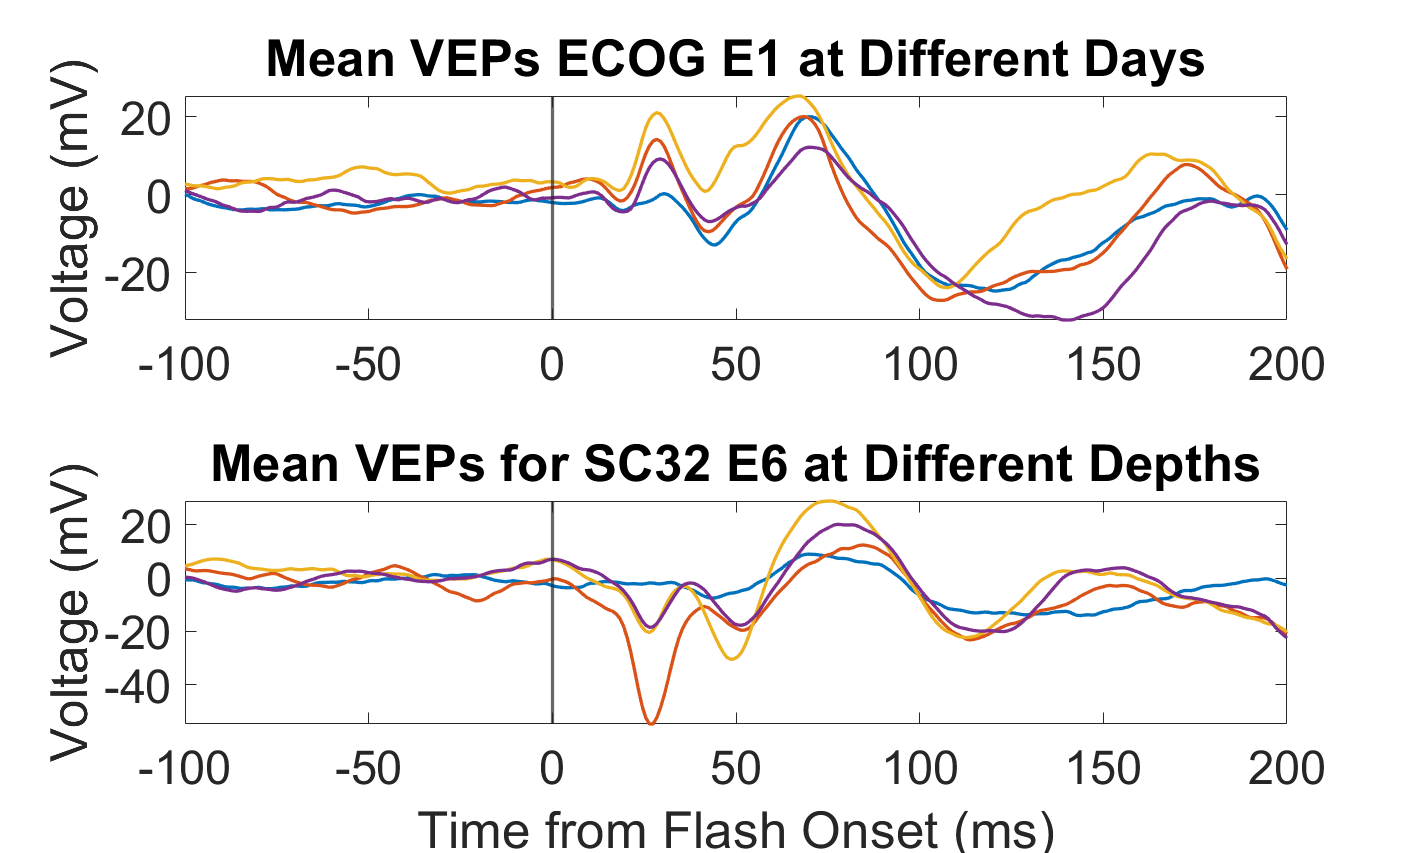

hold off
xlabel('Time from Flash Onset (ms)')
ylabel('Voltage (mV)')
title('Mean VEPs for SC32 E6 at Different Depths')
% legend([num2str(depthProfile_all(2,6)) ' \mum'], ...
%     [num2str(depthProfile_all(8,6)) ' \mum'], ...
%     [num2str(depthProfile_all(12,6)) ' \mum'], ...
%     [num2str(depthProfile_all(16,6)) ' \mum'], ...
%     [num2str(depthProfile_all(20,6)) ' \mum'],...
%     'location',"bestoutside")

set(gca,'fontSize',28)
print(gcf, 'VEPS_mean.jpg', '-djpeg', '-r600');

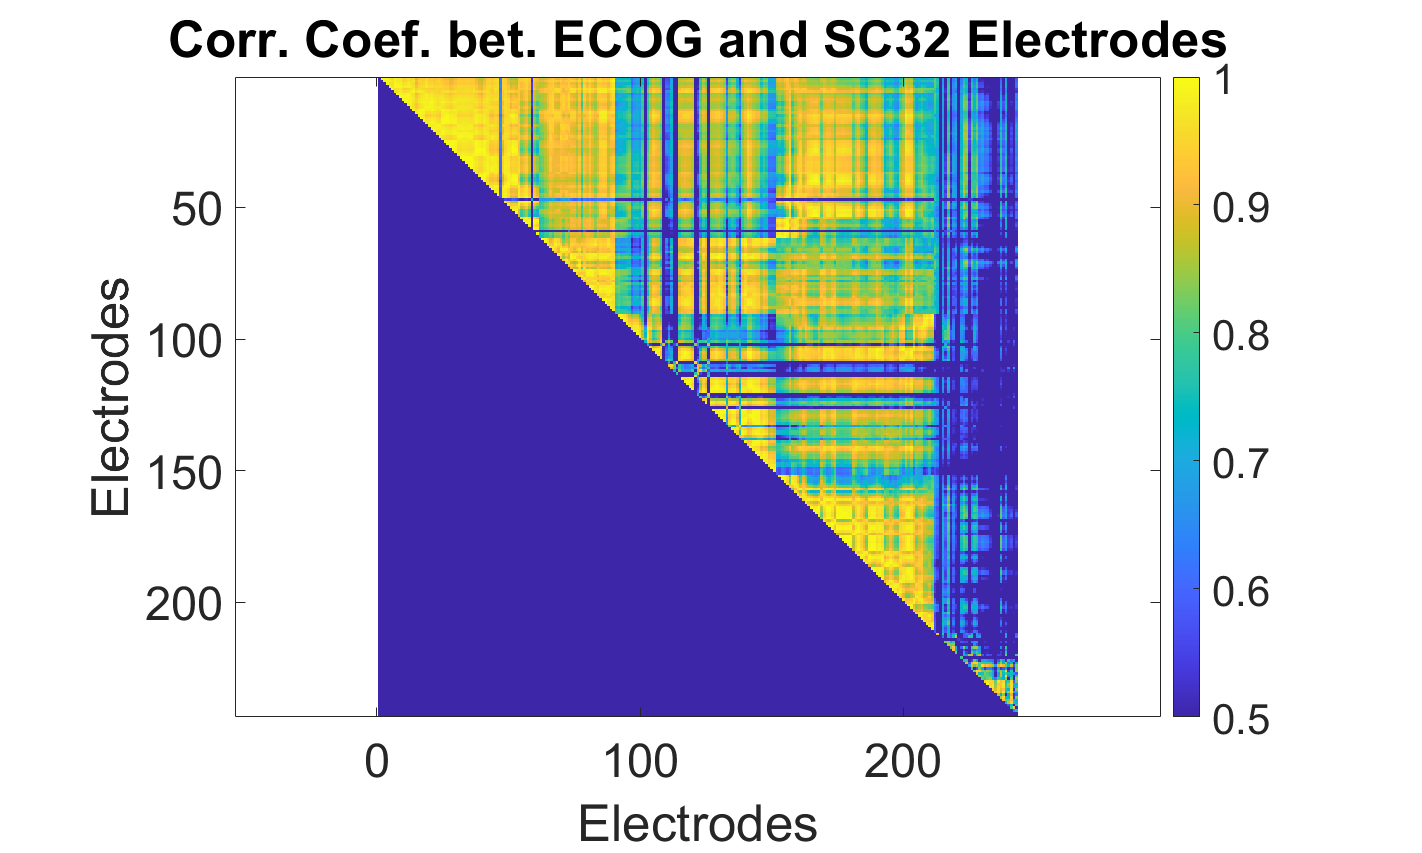

figure('units','normalized','outerposition',[0 0 0.75 0.75])
dayi = 1;
r_visp_e = triu(squeeze(r_visp_e_all(1,:,:)),1);
imagesc(r_visp_e)
title('Corr. Coef. bet. ECOG and SC32 Electrodes')
xlabel('Electrodes')
ylabel('Electrodes')
colorbar
caxis([0.5 1])
set(gca,'fontSize',28)
print(gcf, 'VEPS_matrix.jpg', '-djpeg', '-r600');

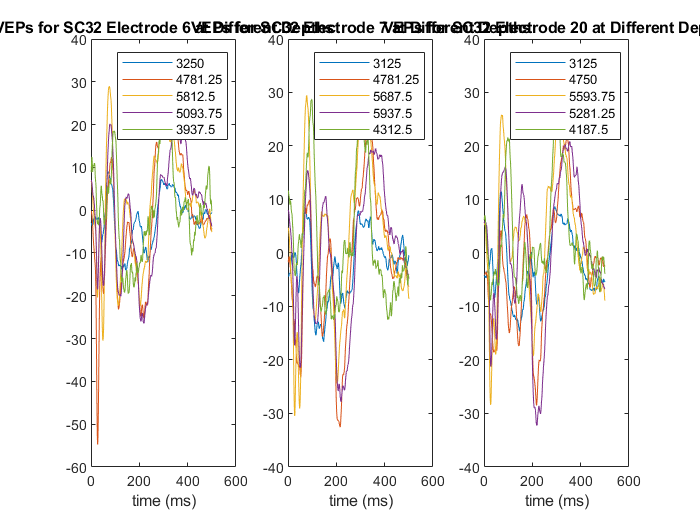



figure
subplot(1,3,1)
plot(squeeze(meanLFP([2,8,12,16,20],211+6,:))')
xlabel('time (ms)')
title('VEPs for SC32 E6 at Different Depths')
legend(num2str(depthProfile_all(2,6)), ...
    num2str(depthProfile_all(8,6)), ...
    num2str(depthProfile_all(12,6)), ...
    num2str(depthProfile_all(16,6)), ...
    num2str(depthProfile_all(20,6)) ...
    )


subplot(1,3,2)
plot(squeeze(meanLFP([2,8,12,16,20],211 + 7,:))')
xlabel('time (ms)')
title('VEPs for SC32 Electrode 7 at Different Depths')
legend(num2str(depthProfile_all(2,7)), ...
    num2str(depthProfile_all(8,7)), ...
    num2str(depthProfile_all(12,7)), ...
    num2str(depthProfile_all(16,7)), ...
    num2str(depthProfile_all(20,7)) ...
    )

subplot(1,3,3)
plot(squeeze(meanLFP([2,8,12,16,20],211 + 20,:))')
xlabel('time (ms)')
title('VEPs for SC32 Electrode 20 at Different Depths')
legend(num2str(depthProfile_all(2,20)), ...
    num2str(depthProfile_all(8,20)), ...
    num2str(depthProfile_all(12,20)), ...
    num2str(depthProfile_all(16,20)), ...
    num2str(depthProfile_all(20,20)) ...
    )

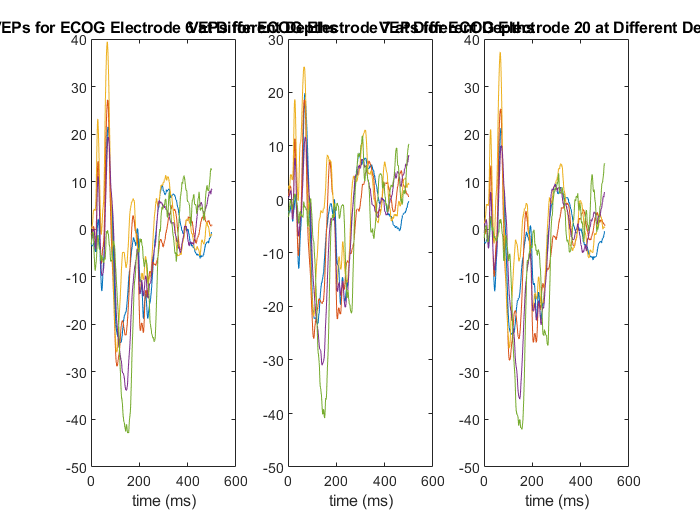

figure
subplot(1,3,1)
plot(squeeze(meanLFP([2,8,12,16,20],1,:))')
xlabel('time (ms)')
title('VEPs for ECOG Electrode 6 at Different Depths')



subplot(1,3,2)
plot(squeeze(meanLFP([2,8,12,16,20], 7,:))')
xlabel('time (ms)')
title('VEPs for ECOG Electrode 7 at Different Depths')


subplot(1,3,3)
plot(squeeze(meanLFP([2,8,12,16,20], 20,:))')
xlabel('time (ms)')
title('VEPs for ECOG Electrode 20 at Different Depths')


%look at the results
figure
pi = 0;
for si = 1:nSess
    for ei = 1:2
        pi = pi + 1;
        subplot(nSess,2, pi )
        plot(squeeze(meanLFP(si,ei,:)))
        if ei == 1
            dN = 'ECOG';
        else
           dN = 'SC32';
        end
        title([DayAnalyze{si} ' ' dN])
    end
end

figure 
for iD = 1:nSess
    subplot(2,4,iD)
    imagesc(squeeze(r_visp_e_all(iD,:,:)))
    title(DayAnalyze{iD})
    caxis([0.5 1])
    colorbar
end


r_SC32 = mean(mean(r_visp_e_all(trialInfo_all(1).N_ECOG + trialInfo.goodSC32, trialInfo_all.N_ECOG + trialInfo.goodSC32),2),2);

Unable to resolve the name trialInfo.goodSC32.

figure
plot(r_ECOG)
hold on
plot(r_SC32)
plot(r_ECOG_SC32)
hold off
legend('ECOG','SC32','ECOG SC32','Location',"east")  
xlabel('Days')
ylabel('Correlation Coefficient')
title('Mean Correlation Coefficient Across Days')
figure
subplot(1,2,1)
r_visp_e_all_SC32_display = r_visp_e_all_SC32;
r_visp_e_all_SC32_display(depthProfile_all == 0) =  nan;
imagesc(r_visp_e_all_SC32_display)
ylabel('Days')
xlabel('SC32 Electrodes')
title('Mean Correlation Coefficient with ECOG')
colorbar

subplot(1,2,2)
imagesc(depthProfile_all)
title('Depth Profile')
xlabel('SC32 Electrodes')
ylabel('Days ')
colorbar


r_visp_e_all_SC32 = squeeze(mean(r_visp_e_all(:,1:211,212:end),2));
figure
hold on
for iD = [31, 19, 24, 25]
    if sum(depthProfile_all(:,iD)) == 0
        continue
    end
    disp(iD)
    [mat_temp, ind_temp ]= sort(depthProfile_all(:,iD));
    scatter(mat_temp,abs(r_visp_e_all_SC32(ind_temp,iD)),2)
end

    31



    19



    24



    25



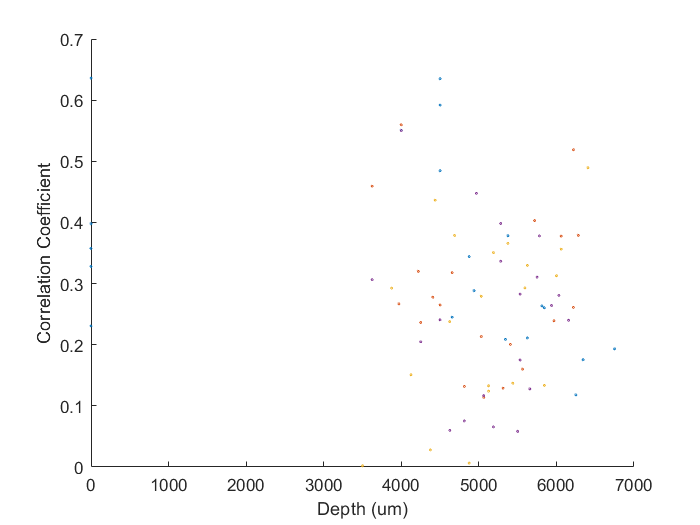

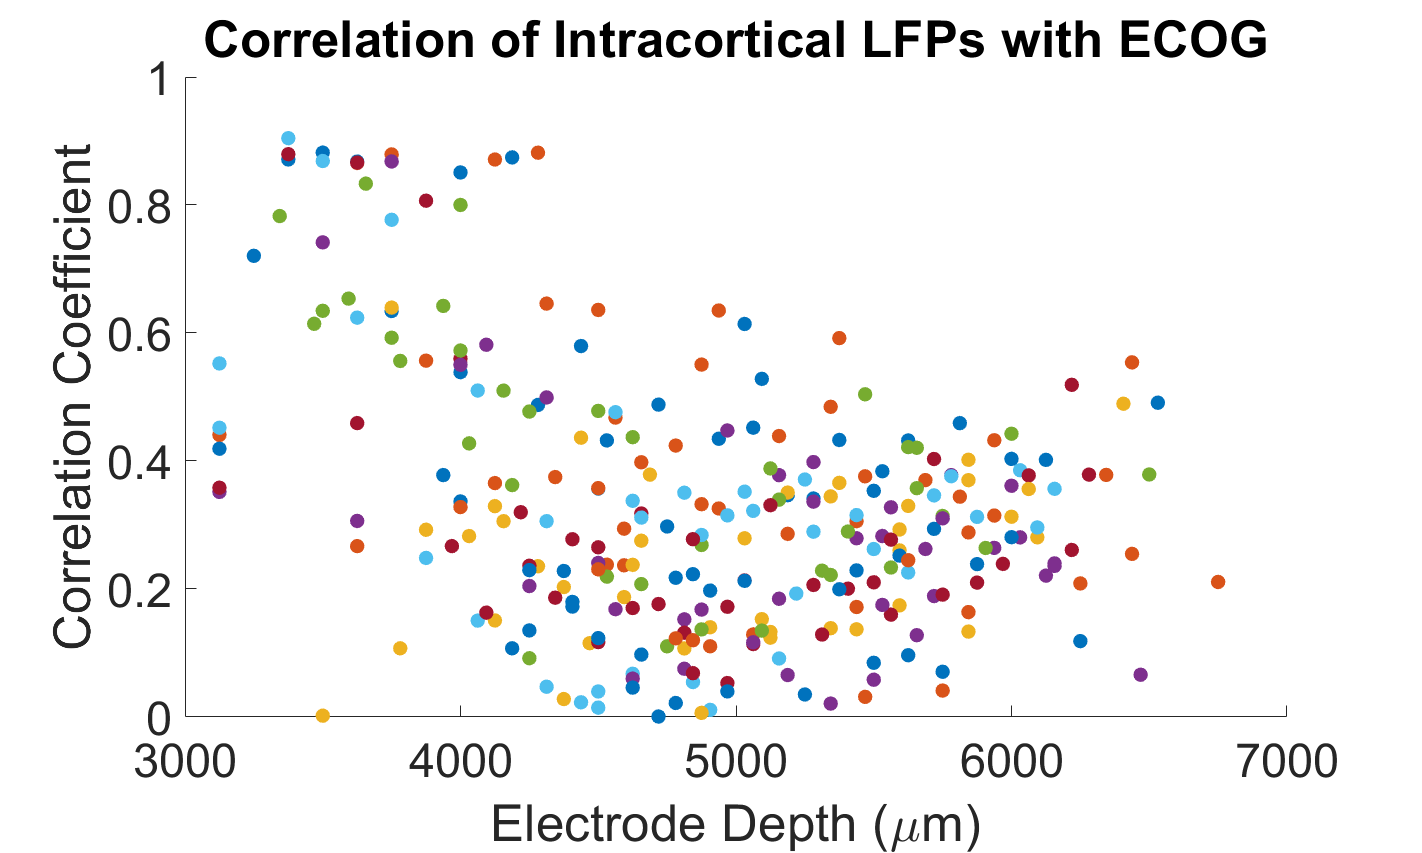

hold off
xlabel('Depth (um)')
ylabel('Correlation Coefficient')
figure('units','normalized','outerposition',[0 0 0.75 0.75])
hold on
for iD = 1:32
    if sum(depthProfile_all(:,iD)) == 0
        continue
    end

    [mat_temp, ind_temp ]= sort(depthProfile_all(:,iD));
    mat_temp = mat_temp(mat_temp > 0);
    ind_temp = ind_temp(mat_temp > 0);
    scatter(mat_temp,abs(r_visp_e_all_SC32(ind_temp,iD)),75,'filled')
end
hold off
xlabel('Electrode Depth (\mum)')
ylabel('Correlation Coefficient')
title('Correlation of Intracortical LFPs with ECOG')
set(gca,'fontSize',28)
print(gcf, 'VEPS_depth.jpg', '-djpeg', '-r600');


%loop through days to double-check they all have trials
day_list = unique(DayAnalyze);
trialDays = getDay(visStimTrials);
disp(['loaded ' num2str(size(visStimTrials,2)) ' vis stim trials.'])
for iD=1:length(day_list)
    trial_idx = ismember(trialDays, day_list{iD});
    if sum(trial_idx)==0
        day_list{iD}
    end
end



%loop through days
useTrial = true(length(visStimTrials),1);
tic
for iD=1:length(day_list)
    iD
    disp(['Analyzing day: ' day_list{iD}])
    %sub-select trials only belonging to this day
    trial_idx = ismember(trialDays, day_list{iD});
    dayTrials = visStimTrials(trial_idx);
    %load all trial data + position info of electrodes
    [trLfpData_ECOG32, eIDs, t, Pchamber_byDay{iD}] = loadTrLFP_session(dayTrials, SessAnalyze(iD,:), 'LM1_ECOG_3', trig, bn, lfpType);
    %load SC32 trials
    [trLfpData_SC32, eIDs, t, Pchamber_byDay{iD}] = loadTrLFP_session(dayTrials, SessAnalyze(iD,:), 'LM1_SC32_1', trig, bn, lfpType);
end
toc
%stack arrays together
trLfpData = cat(2,trLfpData_ECOG32,trLfpData_SC32);
clear 'trLfpData_ECOG32'
clear 'trLfpData_SC32'



What are the questions we would like to explore?

1.  How does the flashing trial differ from motor trials?

2. Can we infer about connectivity in the signal?


ti = 100;
ei = 10;
ei_2 = [6,7, 17,20];

figure   
subplot(2,1,1)
plot(t,squeeze(nanmean(trLfpData(:,ei,:))))
xlabel('time (ms)')
ylabel('Amplitude (au.)')
axis([min(t) max(t) -40 40])
title(sprintf('Averaged Response from %d trials for ECOG electrode %d', size(trLfpData,1), ei))
subplot(2,1,2)
plot(t,squeeze(nanmean(trLfpData(:,ei_2 + N_ECOG,:))))
xlabel('time (ms)')
ylabel('Amplitude (au.)')
axis([min(t) max(t) -40 40])
title(sprintf('Averaged Response from %d trials for SC32 electrode %d', size(trLfpData,1), ei_2))

why doe some electrodes more like the ECOG electrodes?  We have noted that electrode 7 is more similar to those recordings on the surface electrode.  This is adding to our understanding 

figure
imagesc(squeeze((trLfpData(:,ei,:))))
xlabel('Time (ms)')
ylabel('Trial Number')
title(sprintf('All Flashing Trials for Electrode %d', ei))
colorbar

It looks like there is a decrease in the signal about 200 ms after the flash across the trials.

ti = 2;
figure
imagesc(squeeze(trLfpData(ti,:,:)))
xlabel('Time (ms)')
ylabel('Electrode Number')
title(sprintf('All Flashing Trials for Trial %d', ti))
colorbar
figure
imagesc(squeeze(nanmean(trLfpData(:,:,:))))
xlabel('time (ms)')
ylabel('Electrode')
title(sprintf('Averged Response from %d trials for All Electrodes', size(trLfpData,1)))
figure
subplot(2,1,1)
plot(t,squeeze(nanmean(trLfpData(:,1:N_ECOG,:)))')
xlabel('time (ms)')
ylabel('Electrode')
title(sprintf('Averged Response from %d trials for All ECOG Electrodes', size(trLfpData,1)))
subplot(2,1,2)
plot(t,squeeze(nanmean(trLfpData(:,trialInfo.goodSC32 + N_ECOG,:)))')
xlabel('time (ms)')
ylabel('Electrode')
title(sprintf('Averged Response from %d trials for All Lowered SC32 Electrodes', size(trLfpData,1)))

% Look at correlation between different electrodes
time_indx = find(t>=0);
visp = squeeze(nanmean(trLfpData(:,:,time_indx)));

figure
r_visp_e = corrcoef(visp'); % columns are rvs i.e. electrodes, and rows are time points
imagesc(r_visp_e)
xlabel('electrodes')
ylabel('electrodes')
title('180328')
colorbar
caxis([0.6 1])







